%% Apomorphine Test Analysis - Post-Injection Only (30 minutes)
% Arena: 30 cm diameter cylinder
% Camera: 1080x1080 at 25 FPS
% Analysis period: 30 minutes POST-INJECTION ONLY
% FIXED: Automatic calibration for 1080x1080 videos

clear; clc; close all;

%% ===== USER PARAMETERS =====
arena_diameter_cm = 20;      % 30 cm diameter
arena_height_cm = 40;        % Arena height in cm
analysis_duration_min = 30;  % POST-injection analysis duration (minutes)
camera_resolution = [1080, 1080]; % 1080x1080 camera (SQUARE)
fps_manual = 25;             % 25 FPS camera

% Apomorphine-specific parameters
apomorphine_dose = 0.5;      % Dose in mg/kg (adjust based on your experiment)
injection_time = 0;          % Time 0 = injection time (start of recording)
injection_side = 'left';     % 'left' or 'right' - WHICH HEMISPHERE WAS LESIONED/INJECTED?

% Movement thresholds (cm/s) - ADJUSTED FOR REALISTIC MOUSE SPEEDS
locomotion_threshold = 2.0;  % For general movement
stereotypy_threshold = 8.0;  % For repetitive/stereotyped movements
freezing_threshold = 0.5;    % For freezing behavior

% Zone parameters
central_zone_diameter_cm = 15;  % Central zone = half arena diameter (15 cm)

% Rotation analysis parameters
rotation_threshold_deg_s = 30;  % Minimum angular velocity to count as active rotation
full_rotation_angle = 360;      % Degrees for a full rotation

%% ===== DATA LOADING =====
fprintf('=== Apomorphine Test Analysis (Post-Injection Only) ===\n');

=== Apomorphine Test Analysis (Post-Injection Only) ===


fprintf('Arena: %.0f cm diameter cylinder\n', arena_diameter_cm);

Arena: 20 cm diameter cylinder


fprintf('Camera: 1080x1080 at %.0f FPS\n', fps_manual);

Camera: 1080x1080 at 25 FPS


fprintf('Analysis duration: %.0f minutes POST-INJECTION\n', analysis_duration_min);

Analysis duration: 30 minutes POST-INJECTION


fprintf('Apomorphine dose: %.2f mg/kg\n', apomorphine_dose);

Apomorphine dose: 0.50 mg/kg


fprintf('Injection/lesion side: %s hemisphere\n', injection_side);

Injection/lesion side: left hemisphere



% Check for tracking data
if ~exist('track', 'var')
    if exist('Out_Post.mat', 'file')
        load('Out_Post.mat');
        fprintf('Loaded Out_Post.mat\n');
    elseif exist('tracking_data.mat', 'file')
        load('tracking_data.mat');
        fprintf('Loaded tracking_data.mat\n');
    else
        % Try to select file interactively
        [filename, pathname] = uigetfile({'*.mat;*.csv', 'Tracking files'}, ...
                                         'Select POST-INJECTION tracking data');
        if isequal(filename, 0)
            error('No tracking data selected.');
        end
        load(fullfile(pathname, filename));
        fprintf('Loaded %s\n', filename);
    end
end

Loaded Out_Apo_Pd8.mat



%% ===== DATA VALIDATION =====
if ~exist('track', 'var')
    error('No ''track'' variable found in the loaded data.');
end

if ~isstruct(track)
    error('''track'' is not a struct (class: %s).', class(track));
end

fprintf('Available fields in track: %s\n', strjoin(fieldnames(track), ', '));

Available fields in track: Centroid_px, Head_px, Tail_px, Centroid, Head, Tail, Area, Axes, Teta, Time, Velocity, Distance, Vertices, Tracked



%% ===== FRAME RATE & TIME BASE =====
% Use manual FPS since you know your camera is 25 FPS
fps = fps_manual;
dt = 1/fps;  % Time per frame in seconds = 0.04 s
total_frames_expected = analysis_duration_min * 60 * fps;
fprintf('Using manual frame rate: %.0f fps\n', fps);

Using manual frame rate: 25 fps


fprintf('Time per frame (dt): %.3f seconds\n', dt);

Time per frame (dt): 0.040 seconds


fprintf('Expected frames for %.0f min test: %d\n', analysis_duration_min, total_frames_expected);

Expected frames for 30 min test: 45000



%% ===== POSITION DATA EXTRACTION =====
% Find centroid/position data
C = [];
if isfield(track, 'Centroid')
    C = double(track.Centroid);
    fprintf('Using Centroid data (%dx%d)\n', size(C,1), size(C,2));
elseif isfield(track, 'Head')
    C = double(track.Head);
    fprintf('Using Head data (%dx%d)\n', size(C,1), size(C,2));
elseif isfield(track, 'Body_Centroid')
    C = double(track.Body_Centroid);
    fprintf('Using Body_Centroid data (%dx%d)\n', size(C,1), size(C,2));
else
    error('No position data found in track structure.');
end

Using Centroid data (2x53927)



% Handle different coordinate formats
if size(C, 2) == 2 && size(C, 1) > 2
    x = C(:,1);
    y = C(:,2);
elseif size(C, 1) == 2 && size(C, 2) > 2
    x = C(1,:)';
    y = C(2,:)';
else
    error('Unknown coordinate format: %dx%d', size(C,1), size(C,2));
end

% Check position data range
fprintf('\n=== Position Data Diagnostics ===\n');


=== Position Data Diagnostics ===


fprintf('X range: [%.1f, %.1f], span: %.1f pixels\n', min(x), max(x), max(x)-min(x));

X range: [3.6, 16.8], span: 13.3 pixels


fprintf('Y range: [%.1f, %.1f], span: %.1f pixels\n', min(y), max(y), max(y)-min(y));

Y range: [2.3, 16.8], span: 14.6 pixels



% Check if coordinates are within expected 1080x1080 range
if max(x) > 1080 || max(y) > 1080
    fprintf('WARNING: Position data exceeds 1080x1080 bounds\n');
    fprintf('This may indicate incorrect coordinate scaling.\n');
end

% Truncate to expected duration if needed
nFrames = min(total_frames_expected, length(x));
x = x(1:nFrames);
y = y(1:nFrames);
actual_duration_min = nFrames / fps / 60;
fprintf('Actual frames analyzed: %d (%.1f minutes)\n', nFrames, actual_duration_min);

Actual frames analyzed: 45000 (30.0 minutes)



%% ===== AUTOMATIC CALIBRATION FOR 1080x1080 VIDEOS =====
fprintf('\n=== AUTOMATIC CALIBRATION (1080x1080 videos) ===\n');


=== AUTOMATIC CALIBRATION (1080x1080 videos) ===



% Calculate arena bounds from tracking data with 5% margin
x_span = max(x) - min(x);
y_span = max(y) - min(y);
margin = 0.05; % 5% margin

min_x_arena = min(x) - x_span * margin;
max_x_arena = max(x) + x_span * margin;
min_y_arena = min(y) - y_span * margin;
max_y_arena = max(y) + y_span * margin;

% Calculate apparent arena size in pixels
arena_width_px = max_x_arena - min_x_arena;
arena_height_px = max_y_arena - min_y_arena;

% For a circular arena, use the maximum dimension as diameter
apparent_arena_diameter_px = max(arena_width_px, arena_height_px);

% Center of the arena in pixels
center_x = (min_x_arena + max_x_arena) / 2;
center_y = (min_y_arena + max_y_arena) / 2;
arena_radius_px = apparent_arena_diameter_px / 2;

fprintf('Apparent arena diameter from tracking: %.1f pixels\n', apparent_arena_diameter_px);

Apparent arena diameter from tracking: 16.0 pixels


fprintf('Arena center: (%.1f, %.1f) pixels\n', center_x, center_y);

Arena center: (10.2, 9.5) pixels


fprintf('Arena radius: %.1f pixels\n', arena_radius_px);

Arena radius: 8.0 pixels



% For 1080x1080 videos, estimate what portion of the frame the arena occupies
frame_diagonal_px = sqrt(1080^2 + 1080^2); % ~1527 pixels
arena_to_frame_ratio = apparent_arena_diameter_px / 1080;

fprintf('Arena occupies %.1f%% of frame width/height\n', arena_to_frame_ratio * 100);

Arena occupies 1.5% of frame width/height



% Calculate px_to_cm based on known arena diameter (30 cm)
px_to_cm = arena_diameter_cm / apparent_arena_diameter_px;

fprintf('Calculated px_to_cm: %.6f (1 pixel = %.3f cm)\n', px_to_cm, px_to_cm);

Calculated px_to_cm: 1.249449 (1 pixel = 1.249 cm)


fprintf('Arena diameter: %.0f cm = %.0f pixels\n', arena_diameter_cm, apparent_arena_diameter_px);

Arena diameter: 20 cm = 16 pixels



% Check if calibration is reasonable
if px_to_cm < 0.01
    fprintf('WARNING: px_to_cm is very small (%.6f). Arena may appear too large.\n', px_to_cm);
    fprintf('This could indicate tracking coordinates are normalized (0-1 range).\n');
    
    % Check if coordinates are normalized (0-1 range)
    if max(x) <= 1 && max(y) <= 1
        fprintf('Detected normalized coordinates (0-1 range).\n');
        fprintf('Converting to pixel coordinates for 1080x1080 video...\n');
        
        % Convert normalized coordinates to pixels
        x = x * 1080;
        y = y * 1080;
        
        % Recalculate arena bounds
        x_span = max(x) - min(x);
        y_span = max(y) - min(y);
        min_x_arena = min(x) - x_span * margin;
        max_x_arena = max(x) + x_span * margin;
        min_y_arena = min(y) - y_span * margin;
        max_y_arena = max(y) + y_span * margin;
        
        arena_width_px = max_x_arena - min_x_arena;
        arena_height_px = max_y_arena - min_y_arena;
        apparent_arena_diameter_px = max(arena_width_px, arena_height_px);
        
        center_x = (min_x_arena + max_x_arena) / 2;
        center_y = (min_y_arena + max_y_arena) / 2;
        arena_radius_px = apparent_arena_diameter_px / 2;
        
        px_to_cm = arena_diameter_cm / apparent_arena_diameter_px;
        
        fprintf('After conversion:\n');
        fprintf('  Arena diameter: %.1f pixels\n', apparent_arena_diameter_px);
        fprintf('  px_to_cm: %.6f\n', px_to_cm);
    end
elseif px_to_cm > 0.5
    fprintf('WARNING: px_to_cm is very large (%.6f). Arena may appear too small.\n', px_to_cm);
    fprintf('Expected range for 1080x1080: 0.02-0.15 cm/pixel\n');
end

Expected range for 1080x1080: 0.02-0.15 cm/pixel



%% ===== ZONE DEFINITIONS =====
% Convert zone dimensions to pixels
central_radius_px = (central_zone_diameter_cm / 2) / px_to_cm;

% Calculate distance from center for each point
dist_from_center_px = sqrt((x - center_x).^2 + (y - center_y).^2);
dist_from_center_cm = dist_from_center_px * px_to_cm;

% Zone masks (central zone only)
central_mask = dist_from_center_cm <= (central_zone_diameter_cm / 2);
noncentral_mask = ~central_mask;

% Calculate zone occupancy
t_seconds = (0:nFrames-1)' * dt;
t_minutes = t_seconds / 60;

time_in_central = sum(central_mask) * dt;
time_in_noncentral = sum(noncentral_mask) * dt;

percent_central = 100 * time_in_central / (nFrames * dt);
percent_noncentral = 100 * time_in_noncentral / (nFrames * dt);

fprintf('\n--- Zone Occupancy ---\n');


--- Zone Occupancy ---


fprintf('Central zone (%.1f cm diameter): %.1f%% of time\n', central_zone_diameter_cm, percent_central);

Central zone (15.0 cm diameter): 97.1% of time


fprintf('Non-central area: %.1f%% of time\n', percent_noncentral);

Non-central area: 2.9% of time



%% ===== SPEED & LOCOMOTION ANALYSIS =====
% Calculate speed using calibrated values
if nFrames > 1
    dx_cm = diff(x) * px_to_cm;
    dy_cm = diff(y) * px_to_cm;
    distance_cm_frame = [0; sqrt(dx_cm.^2 + dy_cm.^2)];
else
    distance_cm_frame = zeros(nFrames, 1);
end

speed_cm_s = distance_cm_frame / dt;

% Smooth speed for analysis (5-frame moving average = 0.2 seconds at 25 fps)
if nFrames >= 5
    kernel = ones(5,1)/5;
    speed_smoothed = conv(speed_cm_s, kernel, 'same');
    speed_smoothed(1:2) = speed_cm_s(1:2);
    speed_smoothed(end-1:end) = speed_cm_s(end-1:end);
else
    speed_smoothed = speed_cm_s;
end

total_distance_cm = sum(distance_cm_frame);
% FIXED: Calculate cumulative distance here
cumulative_distance = cumsum(distance_cm_frame);

% Movement classification
moving = speed_smoothed > locomotion_threshold;
slow_moving = (speed_smoothed > freezing_threshold) & (speed_smoothed <= locomotion_threshold);
freezing = speed_smoothed <= freezing_threshold;
stereotypy = speed_smoothed > stereotypy_threshold;

time_moving = sum(moving) * dt;
time_slow = sum(slow_moving) * dt;
time_freezing = sum(freezing) * dt;
time_stereotypy = sum(stereotypy) * dt;

percent_moving = 100 * time_moving / (nFrames * dt);
percent_slow = 100 * time_slow / (nFrames * dt);
percent_freezing = 100 * time_freezing / (nFrames * dt);
percent_stereotypy = 100 * time_stereotypy / (nFrames * dt);

mean_speed = mean(speed_smoothed, 'omitnan');
max_speed = max(speed_smoothed);

fprintf('\n--- Locomotion Analysis ---\n');


--- Locomotion Analysis ---


fprintf('Total distance: %.0f cm (%.1f m)\n', total_distance_cm, total_distance_cm/100);

Total distance: 16639 cm (166.4 m)


fprintf('Mean speed: %.2f cm/s | Max speed: %.2f cm/s\n', mean_speed, max_speed);

Mean speed: 9.24 cm/s | Max speed: 157.52 cm/s


fprintf('Moving (>%.1f cm/s): %.1f%% of time\n', locomotion_threshold, percent_moving);

Moving (>2.0 cm/s): 92.2% of time


fprintf('Slow (%.1f-%.1f cm/s): %.1f%% of time\n', freezing_threshold, locomotion_threshold, percent_slow);

Slow (0.5-2.0 cm/s): 7.8% of time


fprintf('Freezing (<%.1f cm/s): %.1f%% of time\n', freezing_threshold, percent_freezing);

Freezing (<0.5 cm/s): 0.0% of time


fprintf('Stereotypy (>%.1f cm/s): %.1f%% of time\n', stereotypy_threshold, percent_stereotypy);

Stereotypy (>8.0 cm/s): 39.5% of time



% Check for unrealistic values
if max_speed > 50
    fprintf('WARNING: Maximum speed (%.1f cm/s) is unrealistic!\n', max_speed);
    fprintf('Expected max for mouse: 20-40 cm/s\n');
    
    % Calculate correction needed
    reasonable_max = 30; % cm/s
    speed_correction = reasonable_max / max_speed;
    fprintf('Suggested speed correction factor: %.4f\n', speed_correction);
    fprintf('This suggests px_to_cm may be %.4f times too large\n', 1/speed_correction);
    
    % Ask user if they want to apply correction
    apply_correction = input('\nApply automatic calibration correction? (1=yes, 0=no): ');
    if apply_correction == 1
        px_to_cm_original = px_to_cm;
        px_to_cm = px_to_cm * speed_correction;
        
        fprintf('Applied correction:\n');
        fprintf('  Original px_to_cm: %.6f\n', px_to_cm_original);
        fprintf('  Corrected px_to_cm: %.6f\n', px_to_cm);
        
        % Recalculate everything with new calibration
        fprintf('\nRecalculating with corrected calibration...\n');
        
        % Recalculate distances and speeds
        dist_from_center_cm = dist_from_center_px * px_to_cm;
        central_mask = dist_from_center_cm <= (central_zone_diameter_cm / 2);
        noncentral_mask = ~central_mask;
        
        if nFrames > 1
            dx_cm = diff(x) * px_to_cm;
            dy_cm = diff(y) * px_to_cm;
            distance_cm_frame = [0; sqrt(dx_cm.^2 + dy_cm.^2)];
            speed_cm_s = distance_cm_frame / dt;
            speed_smoothed = conv(speed_cm_s, kernel, 'same');
            speed_smoothed(1:2) = speed_cm_s(1:2);
            speed_smoothed(end-1:end) = speed_cm_s(end-1:end);
            total_distance_cm = sum(distance_cm_frame);
            cumulative_distance = cumsum(distance_cm_frame);
        end
        
        % Recalculate movement classification
        moving = speed_smoothed > locomotion_threshold;
        slow_moving = (speed_smoothed > freezing_threshold) & (speed_smoothed <= locomotion_threshold);
        freezing = speed_smoothed <= freezing_threshold;
        stereotypy = speed_smoothed > stereotypy_threshold;
        
        mean_speed = mean(speed_smoothed, 'omitnan');
        max_speed = max(speed_smoothed);
        
        fprintf('\n--- Corrected Locomotion Analysis ---\n');
        fprintf('Total distance: %.0f cm\n', total_distance_cm);
        fprintf('Mean speed: %.2f cm/s\n', mean_speed);
        fprintf('Max speed: %.2f cm/s\n', max_speed);
    end
end

Expected max for mouse: 20-40 cm/s


Suggested speed correction factor: 0.1904


This suggests px_to_cm may be 5.2507 times too large


Applied correction:


  Original px_to_cm: 1.249449


  Corrected px_to_cm: 0.237957



Recalculating with corrected calibration...



--- Corrected Locomotion Analysis ---


Total distance: 3169 cm


Mean speed: 1.76 cm/s


Max speed: 30.00 cm/s



if total_distance_cm > 10000
    fprintf('WARNING: Total distance (%.0f cm) is very high!\n', total_distance_cm);
    fprintf('Expected range for 30 min: 2000-5000 cm\n');
end

%% ===== ROTATIONAL BEHAVIOR ANALYSIS =====
if nFrames > 10
    % Calculate angular position relative to center
    angles = atan2(y - center_y, x - center_x); % Returns angles in radians (-pi to pi)
    
    % Calculate angular velocity (rate of change of angle)
    angular_velocity_rad_frame = diff(angles);
    
    % Unwrap angular differences to handle crossing -pi/pi boundary
    angular_velocity_rad_frame(angular_velocity_rad_frame > pi) = angular_velocity_rad_frame(angular_velocity_rad_frame > pi) - 2*pi;
    angular_velocity_rad_frame(angular_velocity_rad_frame < -pi) = angular_velocity_rad_frame(angular_velocity_rad_frame < -pi) + 2*pi;
    
    % Convert to degrees per second for analysis
    angular_velocity_deg_s = rad2deg([0; angular_velocity_rad_frame]) / dt;
    
    % Determine rotation direction based on injection side
    if strcmpi(injection_side, 'left')
        % Left lesion/injection: Contralateral = clockwise (negative angular velocity)
        contralateral_mask = angular_velocity_deg_s < 0;
        ipsilateral_mask = angular_velocity_deg_s > 0;
    else % 'right'
        % Right lesion/injection: Contralateral = counterclockwise (positive angular velocity)
        contralateral_mask = angular_velocity_deg_s > 0;
        ipsilateral_mask = angular_velocity_deg_s < 0;
    end
    
    % Identify frames with active rotation (above threshold)
    active_rotation_mask = abs(angular_velocity_deg_s) > rotation_threshold_deg_s;
    
    % Separate active rotations by direction
    active_contralateral = active_rotation_mask & contralateral_mask;
    active_ipsilateral = active_rotation_mask & ipsilateral_mask;
    
    % Calculate angular displacement (degrees per frame)
    angular_displacement_deg_frame = angular_velocity_deg_s * dt;
    
    % Sum angular displacement for each direction (in degrees)
    total_contralateral_deg = sum(abs(angular_displacement_deg_frame(contralateral_mask)));
    total_ipsilateral_deg = sum(abs(angular_displacement_deg_frame(ipsilateral_mask)));
    
    % Convert to full rotations (360° = 1 rotation)
    full_rotations_contralateral = total_contralateral_deg / 360;
    full_rotations_ipsilateral = total_ipsilateral_deg / 360;
    
    % Calculate rotations per minute
    rotations_per_min_contralateral = full_rotations_contralateral / actual_duration_min;
    rotations_per_min_ipsilateral = full_rotations_ipsilateral / actual_duration_min;
    
    % Calculate net rotational bias
    total_rotation_deg = total_contralateral_deg + total_ipsilateral_deg;
    if total_rotation_deg > 0
        net_rotation_bias = (total_contralateral_deg - total_ipsilateral_deg) / total_rotation_deg;
    else
        net_rotation_bias = 0;
    end
    
    % Time spent rotating in each direction (seconds)
    time_contralateral_rotation = sum(active_contralateral) * dt;
    time_ipsilateral_rotation = sum(active_ipsilateral) * dt;
    percent_time_contralateral = 100 * time_contralateral_rotation / (nFrames * dt);
    percent_time_ipsilateral = 100 * time_ipsilateral_rotation / (nFrames * dt);
    
    % Mean angular velocity for each direction
    mean_angular_velocity_contralateral = mean(abs(angular_velocity_deg_s(active_contralateral)), 'omitnan');
    mean_angular_velocity_ipsilateral = mean(abs(angular_velocity_deg_s(active_ipsilateral)), 'omitnan');
    
    % Calculate cumulative rotations for plotting
    contra_indices = find(contralateral_mask);
    ipsi_indices = find(ipsilateral_mask);
    
    if ~isempty(contra_indices)
        cumulative_contra_deg = cumsum(abs(angular_displacement_deg_frame(contra_indices)));
        cumulative_contra_rot = cumulative_contra_deg / 360;
        contra_times = t_minutes(contra_indices);
    else
        cumulative_contra_rot = [];
        contra_times = [];
    end
    
    if ~isempty(ipsi_indices)
        cumulative_ipsi_deg = cumsum(abs(angular_displacement_deg_frame(ipsi_indices)));
        cumulative_ipsi_rot = cumulative_ipsi_deg / 360;
        ipsi_times = t_minutes(ipsi_indices);
    else
        cumulative_ipsi_rot = [];
        ipsi_times = [];
    end
    
    fprintf('\n=== ROTATIONAL ANALYSIS ===\n');
    fprintf('Injection/Lesion side: %s hemisphere\n', injection_side);
    fprintf('Rotation threshold: %.0f deg/s\n', rotation_threshold_deg_s);
    
    fprintf('\n--- Angular Displacement ---\n');
    fprintf('Contralateral: %.0f degrees\n', total_contralateral_deg);
    fprintf('Ipsilateral: %.0f degrees\n', total_ipsilateral_deg);
    
    fprintf('\n--- Contralateral Rotations (expected) ---\n');
    fprintf('Total rotations: %.1f\n', full_rotations_contralateral);
    fprintf('Rotations per minute: %.2f\n', rotations_per_min_contralateral);
    fprintf('Time spent rotating: %.1f s (%.1f%%)\n', time_contralateral_rotation, percent_time_contralateral);
    
    fprintf('\n--- Ipsilateral Rotations ---\n');
    fprintf('Total rotations: %.1f\n', full_rotations_ipsilateral);
    fprintf('Rotations per minute: %.2f\n', rotations_per_min_ipsilateral);
    fprintf('Time spent rotating: %.1f s (%.1f%%)\n', time_ipsilateral_rotation, percent_time_ipsilateral);
    
    fprintf('\n--- Summary ---\n');
    fprintf('Net rotation bias: %.3f\n', net_rotation_bias);
    fprintf('Percent contralateral: %.1f%%\n', (net_rotation_bias + 1)/2 * 100);
    
    if full_rotations_ipsilateral > 0.1
        fprintf('Contralateral/Ipsilateral ratio: %.2f:1\n', full_rotations_contralateral / full_rotations_ipsilateral);
    else
        fprintf('Contralateral/Ipsilateral ratio: >100:1 (negligible ipsilateral)\n');
    end
    
    % Check for unrealistic rotation counts
    fprintf('\n--- Realism Check ---\n');
    if rotations_per_min_contralateral > 30
        fprintf('WARNING: Contralateral rotations/min (%.1f) is very high!\n', rotations_per_min_contralateral);
        fprintf('Expected range: 5-20 rotations/min\n');
    end
    
    if abs(net_rotation_bias) < 0.5
        fprintf('WARNING: Weak rotation bias (%.3f)\n', net_rotation_bias);
        fprintf('Apomorphine should produce strong contralateral bias (>0.7)\n');
    end
    
    % Create rotation direction array for plotting
    rotation_direction = zeros(size(angular_velocity_deg_s));
    rotation_direction(active_contralateral) = 1;    % Contralateral = 1
    rotation_direction(active_ipsilateral) = 2;      % Ipsilateral = 2
    rotation_direction(~active_rotation_mask) = 0;   % No active rotation = 0
    
else
    fprintf('\n=== ROTATIONAL ANALYSIS ===\n');
    fprintf('Insufficient frames for rotation analysis\n');
end


=== ROTATIONAL ANALYSIS ===


Injection/Lesion side: left hemisphere


Rotation threshold: 30 deg/s



--- Angular Displacement ---


Contralateral: 98799 degrees


Ipsilateral: 141141 degrees



--- Contralateral Rotations (expected) ---


Total rotations: 274.4


Rotations per minute: 9.15


Time spent rotating: 507.2 s (28.2%)



--- Ipsilateral Rotations ---


Total rotations: 392.1


Rotations per minute: 13.07


Time spent rotating: 668.6 s (37.1%)



--- Summary ---


Net rotation bias: -0.176


Percent contralateral: 41.2%


Contralateral/Ipsilateral ratio: 0.70:1



--- Realism Check ---


Apomorphine should produce strong contralateral bias (>0.7)



%% ===== TIME-BINNED ANALYSIS (5-minute bins) =====
bin_duration_min = 5;  % Analyze in 5-minute bins
n_bins = floor(actual_duration_min / bin_duration_min);

fprintf('\n--- Time-Binned Analysis (%.0f-minute bins) ---\n', bin_duration_min);


--- Time-Binned Analysis (5-minute bins) ---



if n_bins > 0
    bin_labels = cell(n_bins, 1);
    bin_means = zeros(n_bins, 1);
    bin_moving = zeros(n_bins, 1);
    bin_central = zeros(n_bins, 1);
    bin_distance = zeros(n_bins, 1);
    
    if exist('full_rotations_contralateral', 'var')
        bin_contra_rotations = zeros(n_bins, 1);
        bin_ipsi_rotations = zeros(n_bins, 1);
    end
    
    for bin = 1:n_bins
        start_frame = round((bin-1) * bin_duration_min * 60 * fps) + 1;
        end_frame = min(round(bin * bin_duration_min * 60 * fps), nFrames);
        
        bin_mask = (1:nFrames)' >= start_frame & (1:nFrames)' <= end_frame;
        
        if sum(bin_mask) > 0
            % Calculate basic metrics
            bin_speed = speed_smoothed(bin_mask);
            bin_moving_vec = moving(bin_mask);
            bin_central_vec = central_mask(bin_mask);
            bin_distance_vec = distance_cm_frame(bin_mask);
            
            bin_means(bin) = mean(bin_speed, 'omitnan');
            bin_moving(bin) = 100 * sum(bin_moving_vec) / sum(bin_mask);
            bin_central(bin) = 100 * sum(bin_central_vec) / sum(bin_mask);
            bin_distance(bin) = sum(bin_distance_vec);
            
            % Calculate rotations for this bin
            if exist('angular_velocity_deg_s', 'var')
                bin_angular_vel = angular_velocity_deg_s(bin_mask);
                bin_angular_disp = abs(bin_angular_vel) * dt;
                
                if strcmpi(injection_side, 'left')
                    bin_contra_mask = bin_angular_vel < 0;
                    bin_ipsi_mask = bin_angular_vel > 0;
                else
                    bin_contra_mask = bin_angular_vel > 0;
                    bin_ipsi_mask = bin_angular_vel < 0;
                end
                
                bin_contra_deg = sum(bin_angular_disp(bin_contra_mask));
                bin_ipsi_deg = sum(bin_angular_disp(bin_ipsi_mask));
                
                bin_contra_rotations(bin) = bin_contra_deg / 360;
                bin_ipsi_rotations(bin) = bin_ipsi_deg / 360;
            end
            
            bin_labels{bin} = sprintf('%d-%d min', (bin-1)*bin_duration_min, bin*bin_duration_min);
            
            fprintf('\nBin %d (%s):\n', bin, bin_labels{bin});
            fprintf('  Mean speed: %.2f cm/s\n', bin_means(bin));
            fprintf('  %% moving: %.1f%%\n', bin_moving(bin));
            fprintf('  %% in center: %.1f%%\n', bin_central(bin));
            fprintf('  Distance: %.1f cm\n', bin_distance(bin));
            
            if exist('angular_velocity_deg_s', 'var')
                fprintf('  Contralateral rotations: %.2f\n', bin_contra_rotations(bin));
                fprintf('  Ipsilateral rotations: %.2f\n', bin_ipsi_rotations(bin));
            end
        end
    end
end


Bin 1 (0-5 min):


  Mean speed: 1.50 cm/s


  % moving: 20.8%


  % in center: 100.0%


  Distance: 451.0 cm


  Contralateral rotations: 33.39


  Ipsilateral rotations: 49.38



Bin 2 (5-10 min):


  Mean speed: 1.82 cm/s


  % moving: 29.7%


  % in center: 100.0%


  Distance: 547.0 cm


  Contralateral rotations: 61.11


  Ipsilateral rotations: 75.77



Bin 3 (10-15 min):


  Mean speed: 1.73 cm/s


  % moving: 27.3%


  % in center: 100.0%


  Distance: 518.1 cm


  Contralateral rotations: 57.47


  Ipsilateral rotations: 66.15



Bin 4 (15-20 min):


  Mean speed: 1.73 cm/s


  % moving: 27.7%


  % in center: 100.0%


  Distance: 520.3 cm


  Contralateral rotations: 41.47


  Ipsilateral rotations: 61.56



Bin 5 (20-25 min):


  Mean speed: 1.82 cm/s


  % moving: 30.7%


  % in center: 100.0%


  Distance: 545.9 cm


  Contralateral rotations: 38.42


  Ipsilateral rotations: 65.82



Bin 6 (25-30 min):


  Mean speed: 1.96 cm/s


  % moving: 35.2%


  % in center: 100.0%


  Distance: 586.7 cm


  Contralateral rotations: 42.57


  Ipsilateral rotations: 73.37


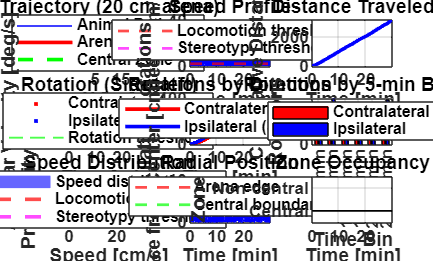


=== Analysis Complete ===


Results saved to: Apomorphine_20cm_30min_Dose0.50_left_2025-12-14_22-05-21_*



%% ===== FIXED PLOTTING =====
set(0, 'DefaultAxesFontSize', 12, 'DefaultAxesFontWeight', 'bold');
set(0, 'DefaultTextFontSize', 12, 'DefaultTextFontWeight', 'bold');

fig1 = figure('Name', sprintf('Apomorphine Test - %.0fcm Arena', arena_diameter_cm), ...
              'NumberTitle', 'off', 'Position', [50 50 1400 900]);

% 1. Trajectory plot
subplot(3,3,1);
h_traj = plot(x, y, 'b-', 'LineWidth', 0.5);
hold on;

% Draw arena circle
theta = linspace(0, 2*pi, 100);
arena_circle_x = center_x + arena_radius_px * cos(theta);
arena_circle_y = center_y + arena_radius_px * sin(theta);
h_arena = plot(arena_circle_x, arena_circle_y, 'r-', 'LineWidth', 2);

% Draw central zone
central_circle_x = center_x + central_radius_px * cos(theta);
central_circle_y = center_y + central_radius_px * sin(theta);
h_central = plot(central_circle_x, central_circle_y, 'g--', 'LineWidth', 2);

xlabel('X [px]'); ylabel('Y [px]');
title(sprintf('Trajectory (%.0f cm arena)', arena_diameter_cm));
legend([h_traj, h_arena, h_central], {'Animal Path', 'Arena Boundary', 'Central Zone'}, ...
       'Location', 'best');
axis equal; grid on;

% Set axis limits to show full arena
xlim([center_x - arena_radius_px*1.1, center_x + arena_radius_px*1.1]);
ylim([center_y - arena_radius_px*1.1, center_y + arena_radius_px*1.1]);

% 2. Speed over time
subplot(3,3,2);
plot(t_minutes, speed_smoothed, 'b-', 'LineWidth', 1);
hold on;
h_loc = yline(locomotion_threshold, 'r--', 'LineWidth', 1.5);
h_stereo = yline(stereotypy_threshold, 'm--', 'LineWidth', 1.5);
xlabel('Time [min]'); ylabel('Speed [cm/s]');
title('Speed Profile');
legend([h_loc, h_stereo], {'Locomotion threshold', 'Stereotypy threshold'}, 'Location', 'best');
grid on;
ylim([0 max(40, max_speed*1.1)]);

% 3. Cumulative distance - FIXED
subplot(3,3,3);
plot(t_minutes, cumulative_distance, 'b-', 'LineWidth', 2);
xlabel('Time [min]'); ylabel('Cumulative Distance [cm]');
title('Distance Traveled');
grid on;

% 4. Angular velocity
subplot(3,3,4);
if exist('angular_velocity_deg_s', 'var')
    % Plot contralateral in red
    contra_idx = find(active_contralateral);
    h_contra = [];
    if ~isempty(contra_idx)
        h_contra = plot(t_minutes(contra_idx), angular_velocity_deg_s(contra_idx), 'r.', ...
            'MarkerSize', 6);
        hold on;
    end
    
    % Plot ipsilateral in blue
    ipsi_idx = find(active_ipsilateral);
    h_ipsi = [];
    if ~isempty(ipsi_idx)
        h_ipsi = plot(t_minutes(ipsi_idx), angular_velocity_deg_s(ipsi_idx), 'b.', ...
            'MarkerSize', 6);
    end
    
    h_thresh = yline(rotation_threshold_deg_s, 'g--', 'LineWidth', 1);
    yline(-rotation_threshold_deg_s, 'g--', 'LineWidth', 1);
    yline(0, 'k-', 'LineWidth', 0.5);
    
    xlabel('Time [min]'); ylabel('Angular Velocity [deg/s]');
    title(sprintf('Rotation (Side: %s)', injection_side));
    
    % Create legend
    legend_items = {};
    legend_handles = [];
    
    if ~isempty(h_contra)
        legend_items{end+1} = 'Contralateral';
        legend_handles(end+1) = h_contra;
    end
    if ~isempty(h_ipsi)
        legend_items{end+1} = 'Ipsilateral';
        legend_handles(end+1) = h_ipsi;
    end
    legend_items{end+1} = 'Rotation threshold';
    legend_handles(end+1) = h_thresh;
    
    legend(legend_handles, legend_items, 'Location', 'best');
    
    grid on;
    
    max_abs_vel = max(abs(angular_velocity_deg_s));
    if max_abs_vel > 0
        ylim([-max_abs_vel*1.1 max_abs_vel*1.1]);
    end
else
    text(0.5, 0.5, 'No rotation data', 'HorizontalAlignment', 'center');
    axis off;
end

% 5. Cumulative rotations
subplot(3,3,5);
if exist('full_rotations_contralateral', 'var')
    h_contra_line = [];
    h_ipsi_line = [];
    
    if ~isempty(contra_times)
        h_contra_line = plot(contra_times, cumulative_contra_rot, 'r-', 'LineWidth', 2);
        hold on;
    end
    if ~isempty(ipsi_times)
        h_ipsi_line = plot(ipsi_times, cumulative_ipsi_rot, 'b-', 'LineWidth', 2);
    end
    
    xlabel('Time [min]'); ylabel('Cumulative Rotations');
    title('Rotations by Direction');
    
    % Create legend
    legend_items = {};
    legend_handles = [];
    
    if ~isempty(h_contra_line)
        legend_items{end+1} = sprintf('Contralateral (%.1f)', full_rotations_contralateral);
        legend_handles(end+1) = h_contra_line;
    end
    if ~isempty(h_ipsi_line)
        legend_items{end+1} = sprintf('Ipsilateral (%.1f)', full_rotations_ipsilateral);
        legend_handles(end+1) = h_ipsi_line;
    end
    
    if ~isempty(legend_handles)
        legend(legend_handles, legend_items, 'Location', 'best');
    end
    
    grid on;
else
    text(0.5, 0.5, 'No rotation data', 'HorizontalAlignment', 'center');
    axis off;
end

% 6. Time-binned rotations
subplot(3,3,6);
if exist('bin_contra_rotations', 'var') && n_bins > 0
    x_pos = 1:n_bins;
    bar_data = [bin_contra_rotations, bin_ipsi_rotations];
    h_bar = bar(x_pos, bar_data, 'grouped');
    set(h_bar(1), 'FaceColor', 'r');
    set(h_bar(2), 'FaceColor', 'b');
    
    xlabel('Time Bin'); ylabel('Rotations');
    title(sprintf('Rotations by %.0f-min Bins', bin_duration_min));
    xticks(x_pos);
    xticklabels(bin_labels);
    legend('Contralateral', 'Ipsilateral', 'Location', 'best');
    grid on;
else
    text(0.5, 0.5, 'No binned rotation data', 'HorizontalAlignment', 'center');
    axis off;
end

% 7. Speed histogram
subplot(3,3,7);
histogram(speed_smoothed, 40, 'FaceColor', 'blue', 'EdgeColor', 'none', 'Normalization', 'probability');
hold on;
xline(locomotion_threshold, 'r--', 'LineWidth', 2);
xline(stereotypy_threshold, 'm--', 'LineWidth', 2);
xlabel('Speed [cm/s]'); ylabel('Probability');
title('Speed Distribution');
legend('Speed distribution', 'Locomotion threshold', 'Stereotypy threshold', 'Location', 'best');
grid on;
xlim([0 min(50, max_speed*1.1)]);

% 8. Distance from center
subplot(3,3,8);
plot(t_minutes, dist_from_center_cm, 'b-', 'LineWidth', 1);
hold on;
h_edge = yline(arena_diameter_cm/2, 'r--', 'LineWidth', 1.5);
h_central_boundary = yline(central_zone_diameter_cm/2, 'g--', 'LineWidth', 1.5);
xlabel('Time [min]'); ylabel('Distance from Center [cm]');
title('Radial Position');
legend([h_edge, h_central_boundary], {'Arena edge', 'Central boundary'}, 'Location', 'best');
grid on;
ylim([0 arena_diameter_cm/2 * 1.1]);

% 9. Zone occupancy
subplot(3,3,9);
zone_plot = zeros(size(t_minutes));
zone_plot(central_mask) = 1;
zone_plot(noncentral_mask) = 2;
plot(t_minutes, zone_plot, 'k-', 'LineWidth', 1);
xlabel('Time [min]'); ylabel('Zone');
title('Zone Occupancy');
yticks([1 2]);
yticklabels({'Central', 'Non-central'});
ylim([0.5 2.5]);
grid on;

%% ===== SAVE RESULTS =====
timestamp = datetime('now', 'Format', 'yyyy-MM-dd_HH-mm-ss');
baseFilename = sprintf('Apomorphine_%.0fcm_%.0fmin_Dose%.2f_%s_%s', ...
                      arena_diameter_cm, analysis_duration_min, apomorphine_dose, injection_side, timestamp);

try
    saveas(fig1, sprintf('%s_overview.png', baseFilename));
    
    % Save summary to text file
    fid = fopen(sprintf('%s_summary.txt', baseFilename), 'w');
    fprintf(fid, 'APOMORPHINE TEST SUMMARY\n');
    fprintf(fid, '=======================\n\n');
    fprintf(fid, 'Arena: %.0f cm diameter\n', arena_diameter_cm);
    fprintf(fid, 'Camera: 1080x1080 at %.0f FPS\n', fps);
    fprintf(fid, 'Duration: %.1f minutes\n', actual_duration_min);
    fprintf(fid, 'Dose: %.2f mg/kg\n', apomorphine_dose);
    fprintf(fid, 'Injection side: %s\n\n', injection_side);
    fprintf(fid, 'Calibration: 1 pixel = %.6f cm\n', px_to_cm);
    fprintf(fid, 'Arena diameter in pixels: %.1f\n\n', apparent_arena_diameter_px);
    
    fprintf(fid, 'LOCOMOTION:\n');
    fprintf(fid, '  Total distance: %.0f cm\n', total_distance_cm);
    fprintf(fid, '  Mean speed: %.2f cm/s\n', mean_speed);
    fprintf(fid, '  Max speed: %.2f cm/s\n', max_speed);
    fprintf(fid, '  %% Moving: %.1f\n', percent_moving);
    fprintf(fid, '  %% Freezing: %.1f\n', percent_freezing);
    fprintf(fid, '  %% Stereotypy: %.1f\n', percent_stereotypy);
    fprintf(fid, '  %% Center: %.1f\n\n', percent_central);
    
    if exist('full_rotations_contralateral', 'var')
        fprintf(fid, 'ROTATIONAL BEHAVIOR:\n');
        fprintf(fid, '  Contralateral rotations: %.1f (%.2f/min)\n', ...
                full_rotations_contralateral, rotations_per_min_contralateral);
        fprintf(fid, '  Ipsilateral rotations: %.1f (%.2f/min)\n', ...
                full_rotations_ipsilateral, rotations_per_min_ipsilateral);
        fprintf(fid, '  Net bias: %.3f\n', net_rotation_bias);
        fprintf(fid, '  %% time contralateral: %.1f\n', percent_time_contralateral);
        fprintf(fid, '  %% time ipsilateral: %.1f\n', percent_time_ipsilateral);
    end
    
    fclose(fid);
    
    % Save data to MAT file
    save(sprintf('%s_data.mat', baseFilename), 't_minutes', 'speed_smoothed', ...
         'cumulative_distance', 'dist_from_center_cm', 'central_mask', ...
         'px_to_cm', 'apparent_arena_diameter_px');
    
    if exist('angular_velocity_deg_s', 'var')
        save(sprintf('%s_data.mat', baseFilename), 'angular_velocity_deg_s', ...
             'full_rotations_contralateral', 'full_rotations_ipsilateral', ...
             'net_rotation_bias', '-append');
    end
    
    fprintf('\n=== Analysis Complete ===\n');
    fprintf('Results saved to: %s_*\n', baseFilename);
    
catch ME
    warning('Error saving files: %s', ME.message);
end


%% ===== FINAL SUMMARY =====
fprintf('\n===========================================\n');

fprintf('FINAL SUMMARY\n');

FINAL SUMMARY


fprintf('===========================================\n');

fprintf('Video: 1080x1080 at 25 FPS\n');

Video: 1080x1080 at 25 FPS


fprintf('Arena: %.0f cm diameter\n', arena_diameter_cm);

Arena: 20 cm diameter


fprintf('Calibration: 1 pixel = %.4f cm\n', px_to_cm);

Calibration: 1 pixel = 0.2380 cm


fprintf('Arena in pixels: %.0f px diameter\n', apparent_arena_diameter_px);

Arena in pixels: 16 px diameter


fprintf('\nResults:\n');


Results:


fprintf('  Total distance: %.0f cm\n', total_distance_cm);

  Total distance: 3169 cm


fprintf('  Mean speed: %.2f cm/s\n', mean_speed);

  Mean speed: 1.76 cm/s


fprintf('  Max speed: %.2f cm/s\n', max_speed);

  Max speed: 30.00 cm/s


fprintf('  Center time: %.1f%%\n', percent_central);

  Center time: 97.1%



if exist('full_rotations_contralateral', 'var')
    fprintf('  Contralateral rotations: %.1f (%.2f/min)\n', full_rotations_contralateral, rotations_per_min_contralateral);
    fprintf('  Ipsilateral rotations: %.1f (%.2f/min)\n', full_rotations_ipsilateral, rotations_per_min_ipsilateral);
    fprintf('  Rotation bias: %.3f (%.0f%% contralateral)\n', net_rotation_bias, (net_rotation_bias + 1)/2 * 100);
end

  Contralateral rotations: 274.4 (9.15/min)


  Ipsilateral rotations: 392.1 (13.07/min)


  Rotation bias: -0.176 (41% contralateral)



fprintf('\nExpected ranges for apomorphine (0.5 mg/kg):\n');


Expected ranges for apomorphine (0.5 mg/kg):


fprintf('  Total distance: 2000-5000 cm\n');

  Total distance: 2000-5000 cm


fprintf('  Mean speed: 1.5-3.0 cm/s\n');

  Mean speed: 1.5-3.0 cm/s


fprintf('  Max speed: 20-40 cm/s\n');

  Max speed: 20-40 cm/s


fprintf('  Contralateral rotations: 300-800 total\n');

  Contralateral rotations: 300-800 total


fprintf('  Rotation bias: 0.7-0.9 (85-95%% contralateral)\n');

  Rotation bias: 0.7-0.9 (85-95% contralateral)


fprintf('===========================================\n');